# Building Regression Models - Nonparametric Models

## 3. SVMs and Decision Trees

### Course Example: Fuel Economy

Load fuel economy data and view the relationships between the numeric predictors and response.

load carEcon
carData

carData = 2587×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    PRP    FuelType    City_Highway    Valves_Cyl    FuelEcon
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ___    ________    ____________    __________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         city              4          3.5318 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           29.1        N     31        61         highway           4          3.6187 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         highway           4          3.6299 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           2

### 3.1. Fit a SVM predictor linear model of fuel economy

% mdl=fitrsvm(carTrain,'FuelEcon')

Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

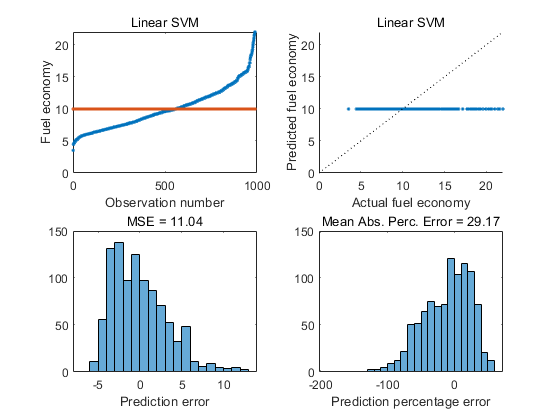

econPred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'Linear SVM')

Standardize variables

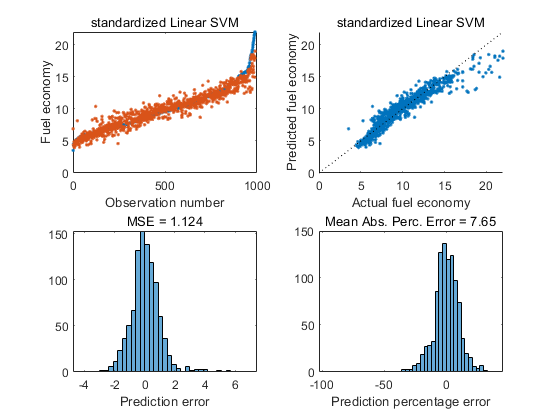

mdl=fitrsvm(carTrain,'FuelEcon','Standardize',true);
econPred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'standardized Linear SVM')

Try a Gaussian kernel SVM

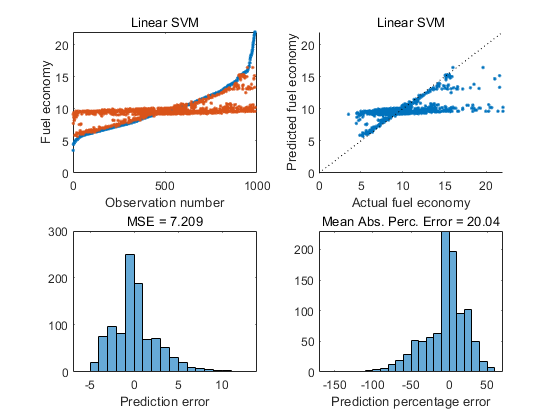

mdl=fitrsvm(carTrain,'FuelEcon','KernelFunction','gaussian');
econPred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'Linear SVM')

### 3.2. Fit a Decision Tree linear model of fuel economy

mdl=fitrtree(carTrain,'FuelEcon');

Predict fuel economy for the test data and compare the result with the actual fuel economy of the test data.

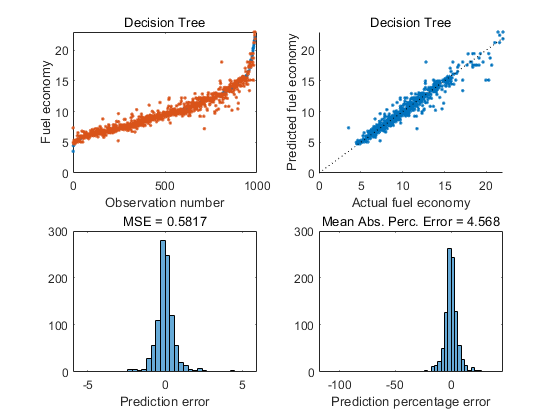

econPred=predict(mdl, carTest);
evaluatefit(carTest.FuelEcon,econPred,'Decision Tree')

Prune the tree

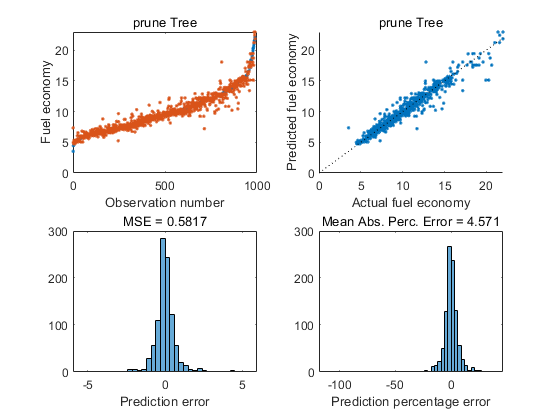

mdl = prune(mdl,'Level', 10);
econPred=predict(mdl, carTest);
evaluatefit(carTest.FuelEcon,econPred,'prune Tree')

Set minimum leaf size

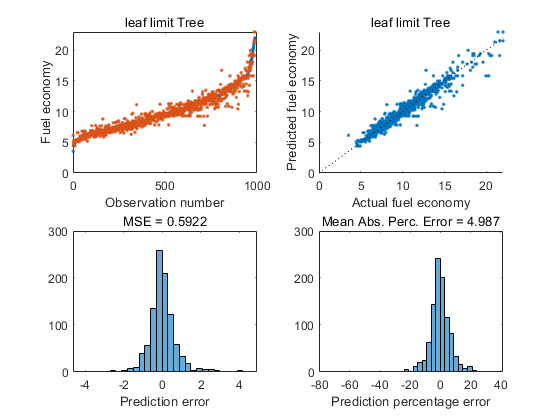

mdl=fitrtree(carTrain,'FuelEcon','MinLeafSize',5);
econPred=predict(mdl, carTest);
evaluatefit(carTest.FuelEcon,econPred,'leaf limit Tree')

## 4. Gaussian Process Regression

Fit and evaluate Gaussian process models of fuel economy.

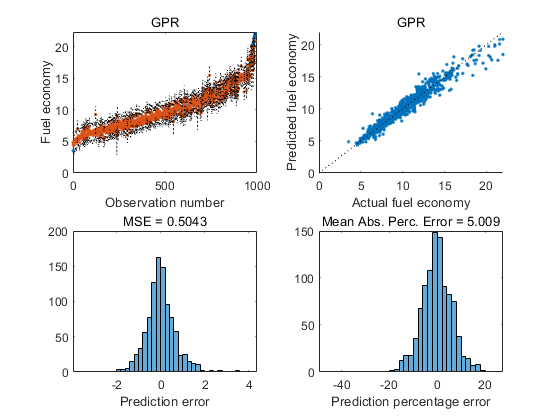

mdl=fitrgp(carTrain,'FuelEcon');
[econPred, econStd, econInt] = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'GPR')
subplot(2,2,1) % Add prediction intervals
hold on
plot(econInt,'k:')

Try a different kernel - Matern

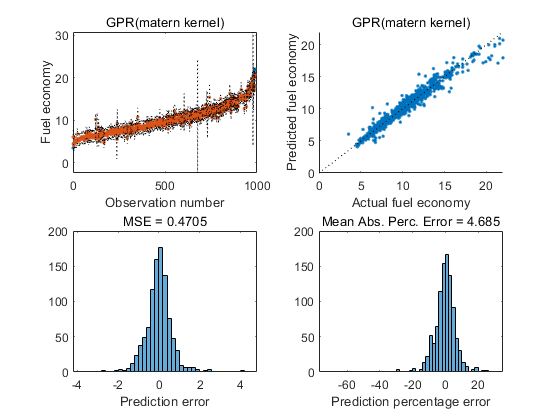

mdl=fitrgp(carTrain,'FuelEcon','KernelFunction','matern32');
[econPred, econStd, econInt] = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'GPR(matern kernel)')
subplot(2,2,1) % Add prediction intervals
hold on
plot(econInt,'k:')

Try a different kernel - Automatic Relevance Determination Squared Exponential

You can choose a kernel function which uses a separate length scale for each predictor. Such kernel functions have names which start with `"ard".`

tic
mdl=fitrgp(carTrain,'FuelEcon','KernelFunction','ardsquaredexponential');
[econPred, econStd, econInt] = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,econPred,'GPR(ardmatern32 kernel)')
subplot(2,2,1) % Add prediction intervals
hold on
plot(econInt,'k:')
toc